# Exercise

Chat with Chat can be found here: [https://chat.openai.com/share/f9b0d3af-6b95-4ca2-9620-9aa0bfd664b7](https://chat.openai.com/share/f9b0d3af-6b95-4ca2-9620-9aa0bfd664b7) 

In this exercise we will run through an example of correcting for multiple comparisons with both the Benjamini-Hochberg procedure and the more conservative Bonferroni correction.

First, simulate multiple (say, 1000) t-tests comparing two samples with equal means and standard deviations, and save the p-values. Obviously, at p<0.05 we expect that ~5% of the simulations to yield a "statistically significant" result (of rejecting the NULL hypothesis that the samples come from distributions with equal means).

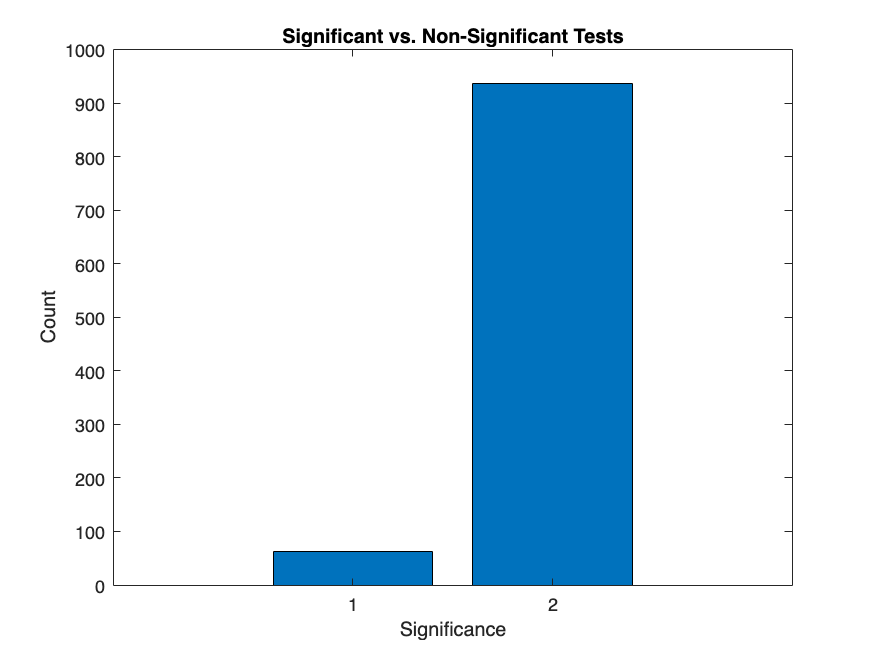

% Initialize variables
num_tests = 1000;
sample_size = 20; % Adjust sample size as needed
alpha = 0.05;
significant_count = 0;

% Initialize array to store p-values
p_values = zeros(num_tests, 1);

% Simulate t-tests
for i = 1:num_tests
    % Generate random samples with equal mean and standard deviation
    sample1 = randn(sample_size, 1);
    sample2 = randn(sample_size, 1);
    
    [~, p_value] = ttest2(sample1, sample2);
    p_values(i) = p_value;
    
    if p_value < alpha
        significant_count = significant_count + 1;
    end
end

% Plot the results
figure;
bar([significant_count, num_tests-significant_count]);
title('Significant vs. Non-Significant Tests');
xlabel('Significance');
ylabel('Count');


% Display the percentage of significant tests
disp(['Percentage of significant tests: ', num2str((significant_count/num_tests)*100), '%']);

Percentage of significant tests: 6.3%


Second, once you have the simulated p-values, apply both methods to address the multiple comparisons problem.

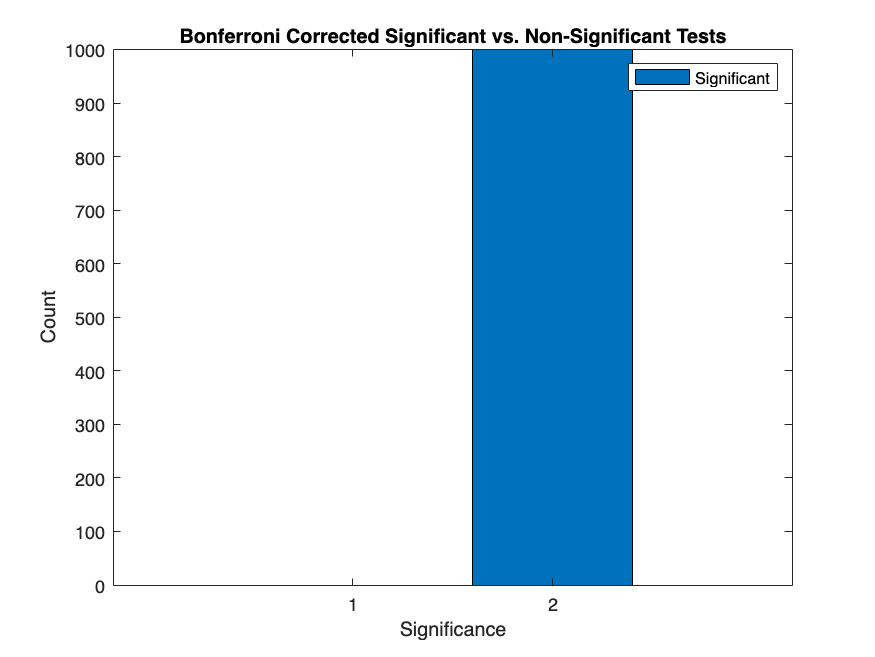

% Apply Bonferroni correction
significant_count_bonferroni = sum(p_values < alpha/num_tests);

% Plot the results
figure;
bar([significant_count_bonferroni, num_tests-significant_count_bonferroni]);
title('Bonferroni Corrected Significant vs. Non-Significant Tests');
xlabel('Significance');
ylabel('Count');
legend('Significant', 'Non-Significant');


% Display the percentage of significant tests (Bonferroni corrected)
disp(['Percentage of significant tests (Bonferroni corrected): ', num2str((significant_count_bonferroni/num_tests)*100), '%']);

Percentage of significant tests (Bonferroni corrected): 0%


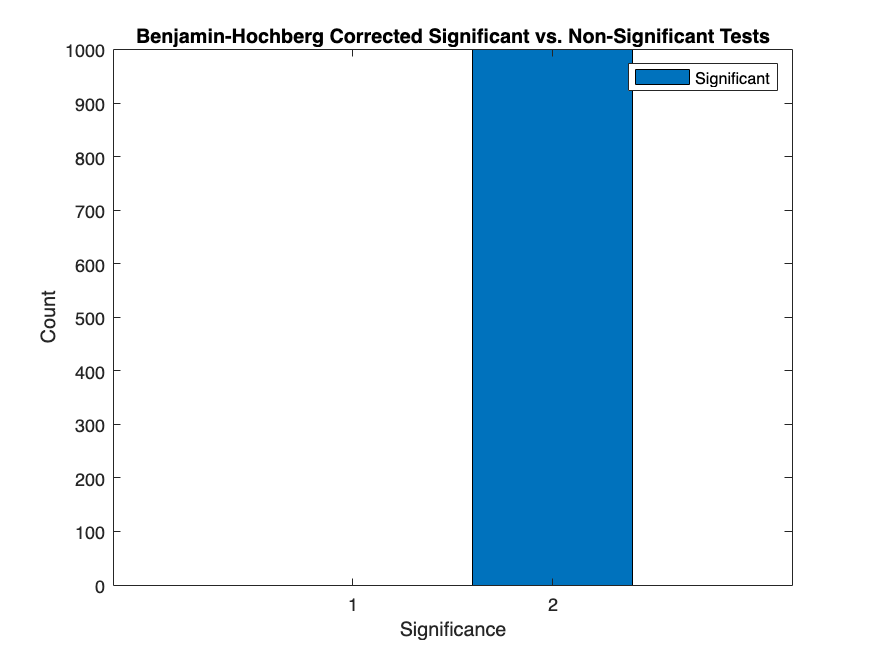

% Apply Benjamin-Hochberg correction
[sorted_p_values, idx] = sort(p_values);
threshold = (1:num_tests) * alpha / num_tests;
significant_count_benjamin_hochberg = sum(sorted_p_values < threshold');

% Plot the results
figure;
bar([significant_count_benjamin_hochberg, num_tests-significant_count_benjamin_hochberg]);
title('Benjamin-Hochberg Corrected Significant vs. Non-Significant Tests');
xlabel('Significance');
ylabel('Count');
legend('Significant', 'Non-Significant');


% Display the percentage of significant tests (Benjamin-Hochberg corrected)
disp(['Percentage of significant tests (Benjamin-Hochberg corrected): ', num2str((significant_count_benjamin_hochberg/num_tests)*100), '%']);

Percentage of significant tests (Benjamin-Hochberg corrected): 0%


Third, set the sample 1 and sample 2 means to be 1 and 2 respectively, and re-run the exercise. What do you notice? What if you make the difference between means even greater?

% Initialize variables
num_tests = 1000;
sample_size = 20; % Adjust sample size as needed
alpha = 0.05;
significant_count_uncorrected = 0;
significant_count_bonferroni = 0;
significant_count_benjamin_hochberg = 0;

% Initialize array to store p-values
p_values = zeros(num_tests, 1);

% Simulate t-tests
for i = 1:num_tests
    % Generate random samples with different means and equal standard deviation
    sample1 = randn(sample_size, 1) + 1;
    sample2 = randn(sample_size, 1) + 2;
    
    [~, p_value] = ttest2(sample1, sample2);
    p_values(i) = p_value;
    
    if p_value < alpha
        significant_count_uncorrected = significant_count_uncorrected + 1;
    end
end

% Apply Bonferroni correction
significant_count_bonferroni = sum(p_values < alpha/num_tests);

% Apply Benjamin-Hochberg correction
[sorted_p_values, idx] = sort(p_values);
threshold = (1:num_tests) * alpha / num_tests;
significant_count_benjamin_hochberg = sum(sorted_p_values < threshold');

% Display the results
disp(['Percentage of significant tests (Uncorrected): ', num2str((significant_count_uncorrected/num_tests)*100), '%']);

Percentage of significant tests (Uncorrected): 86.9%


disp(['Percentage of significant tests (Bonferroni corrected): ', num2str((significant_count_bonferroni/num_tests)*100), '%']);

Percentage of significant tests (Bonferroni corrected): 9.2%


disp(['Percentage of significant tests (Benjamin-Hochberg corrected): ', num2str((significant_count_benjamin_hochberg/num_tests)*100), '%']);

Percentage of significant tests (Benjamin-Hochberg corrected): 85.4%


If you increase the difference between the means (e.g., set sample 1 mean to 1 and sample 2 mean to 3), you would generally expect to see a larger proportion of statistically significant results across all correction methods, as the samples are more distinct from each other. This is because a larger difference in means leads to a larger effect size, which in turn increases the power of the statistical tests.